addpath("MALSAR/MALSAR/functions/calibration")
addpath("MALSAR/MALSAR/functions/mutli-task clustering")
addpath("MALSAR/MALSAR/utils")

% Simulation
trueW = zeros(30, 30);
rng('default');
for k = 1: 3
    for j = 1: 10
        trueW(10*(k-1)+1: 10*k, 10*(k-1)+j) = normrnd(0, 5, [1, 10]);
    end
end
trueW

trueW =     2.6883   -6.7494    3.3575    4.4420   -0.5112   -4.3183   -5.4453   -3.0780    7.0966   -5.7398         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    9.1694   15.1746   -6.0374   -5.7354   -1.2072    0.3868    0.1628    3.7404    1.4579    0.5244         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
  -11.2942    3.6270    3.5862   -5.3444    1.5960   -6.0706    2.7626   -0.9621    0.9891    3.6113         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.3109   -0.3153    8.1512   -4.0475    1.5643   -5.5675    5.5031    4.4431    7.938

X = {};
Y = {};
for i = 1: 30
    X{i} = normrnd(0, 5, [30, 30]);
    Y{i} = X{i} * trueW(:, i) + normrnd(0, 1, [30, 1]);
end

% model performance.
w = multitask_admm(Y, X, 1, 1, 1e-5, 1, 2)

initilization done
r&c done
Iteration:  800

w =     2.5826   -6.5707    3.2638    3.4298   -0.1799   -4.3488   -5.2597   -1.7240    7.0783   -5.7426    0.1767    0.0951    0.0283   -0.7046    0.0700   -0.2525   -0.1284    0.2052    0.0272    0.2308   -0.1567   -0.2214    0.1924   -0.1326    0.0289    0.4347    0.2128    0.2585   -0.3709   -0.3624
    7.3626   14.8019   -5.8967   -5.0249   -1.0111    0.2048    0.3019    3.3324    1.3934    0.5795    0.0721    0.0123    0.1723    0.1658    0.0918    0.0594   -0.0892   -0.1387    0.2123    0.6043   -0.0346   -0.1102    0.2076    0.1682   -0.3142   -0.1608    0.0483    0.1975    0.4305    0.1839
  -10.2097    3.0681    3.5474   -4.3324    1.5643   -6.1673    2.3769    0.2527    0.9373    3.7533   -0.1903   -0.0536    0.1202   -0.2959   -0.7736    0.1915    0.3476    0.1707    0.0596    0.2862   -0.1334    0.2359   -0.1234    0.0338    0.7586    0.1585    0.1192    0.1668   -0.0101   -0.0340
    5.9209   -0.9320    8.3104   -3.3137    1.3663   -5.5601    5.2936    3.2865    7.6921   

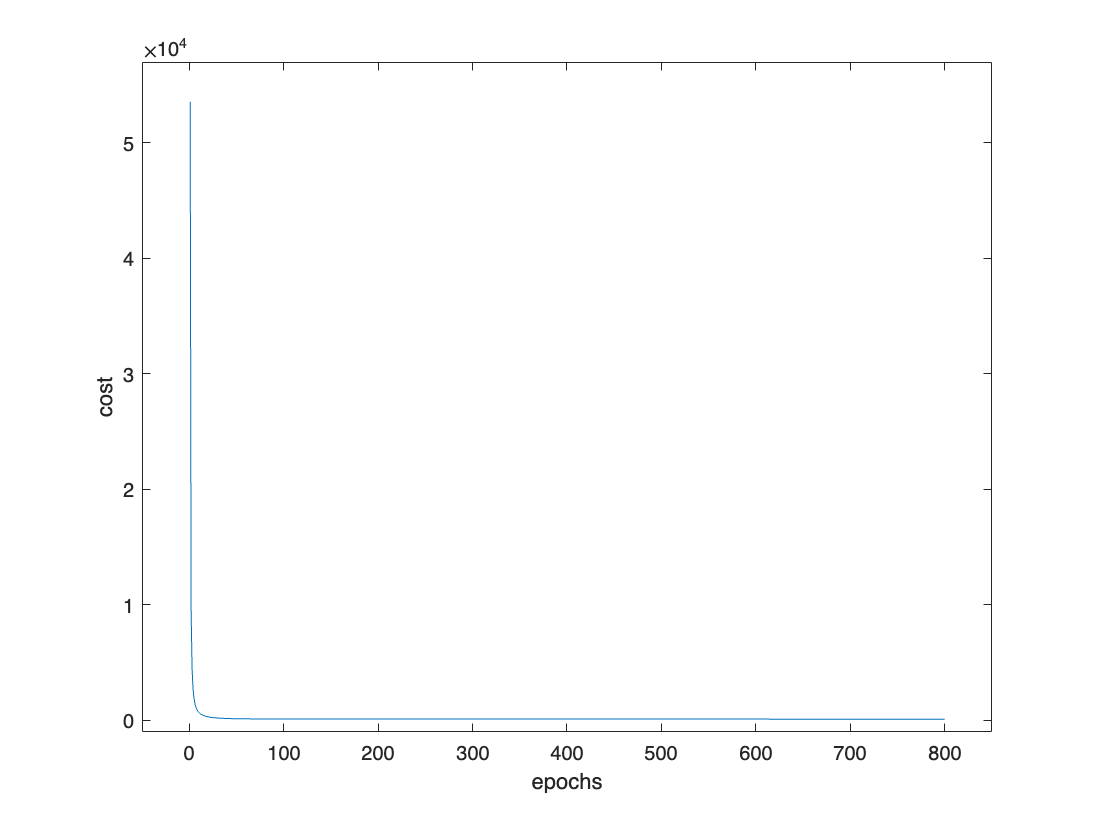

xlim([-50, 850])
ylim([-1000, 57000])
xlabel('epochs');
ylabel('cost');

initilization done
r&c done
Iteration:  800

ans = 0.6652

initilization done
r&c done
Iteration:  800

ans = 0.6730

initilization done
r&c done
Iteration:  800

ans = 0.6807

initilization done
r&c done
Iteration:  800

ans = 0.6881

initilization done
r&c done
Iteration:  800

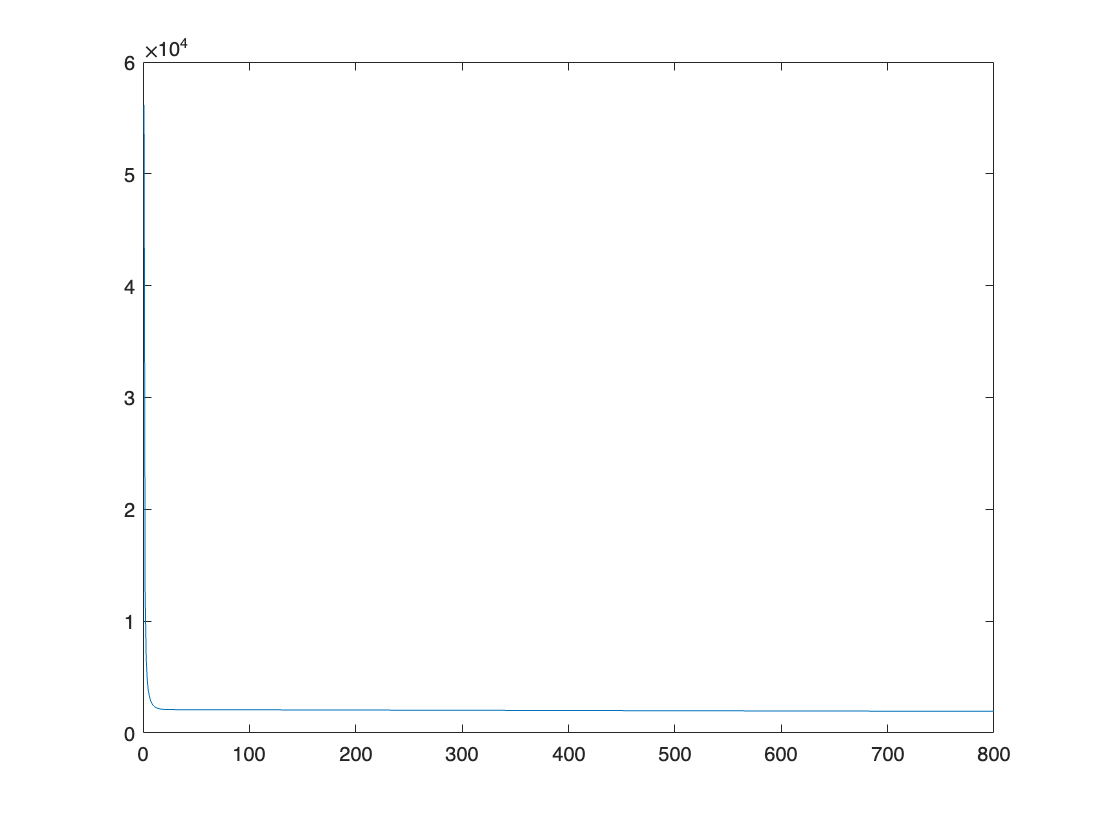

ans = 0.6954

for i = 1: 5
    w = multitask_admm(Y, X, 1, 1, 1e-5, i, 1);
    sqrt(norm(w - trueW, "fro")^2/900)
end

initilization done
r&c done
Iteration:  800

ans = 0.6652

initilization done
r&c done
Iteration:  800

ans = 0.6712

initilization done
r&c done
Iteration:  800

ans = 0.6771

initilization done
r&c done
Iteration:  800

ans = 0.6831

initilization done
r&c done
Iteration:  800

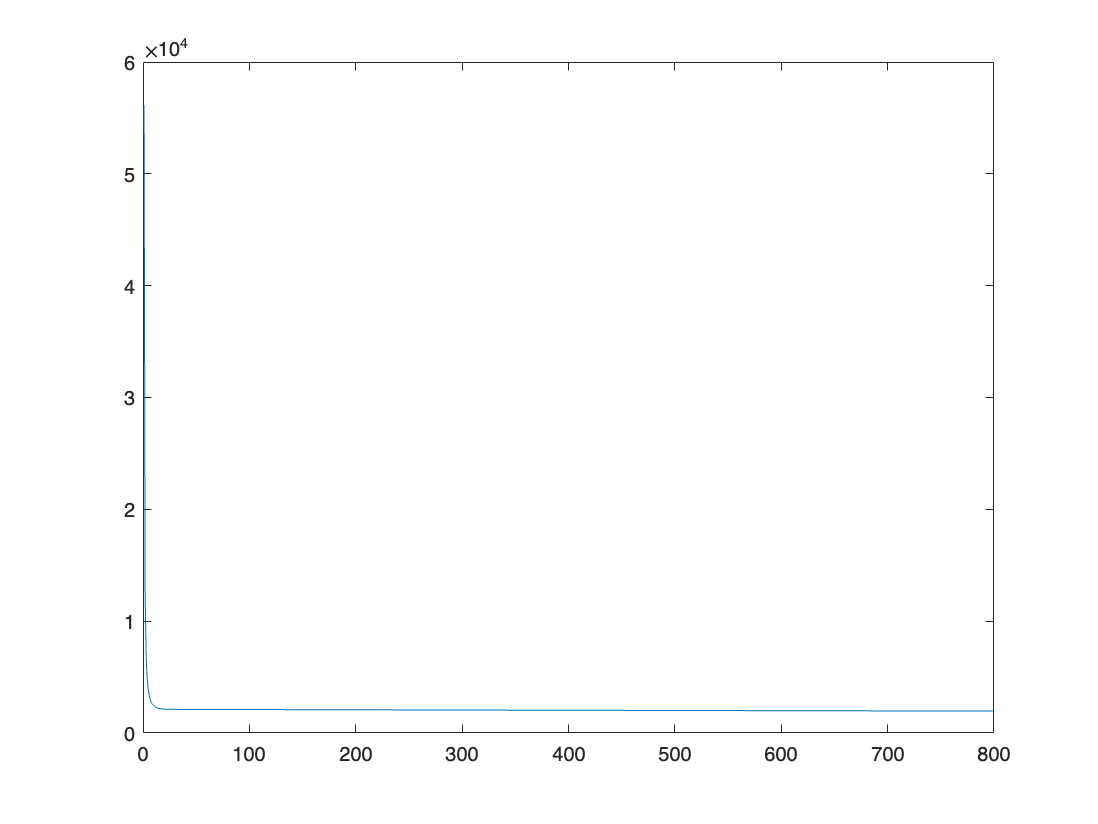

ans = 0.6891

for i = 1: 5
    w = multitask_admm(Y, X, 1, 1, 1e-5, 1, i);
    sqrt(norm(w - trueW, "fro")^2/900)
end

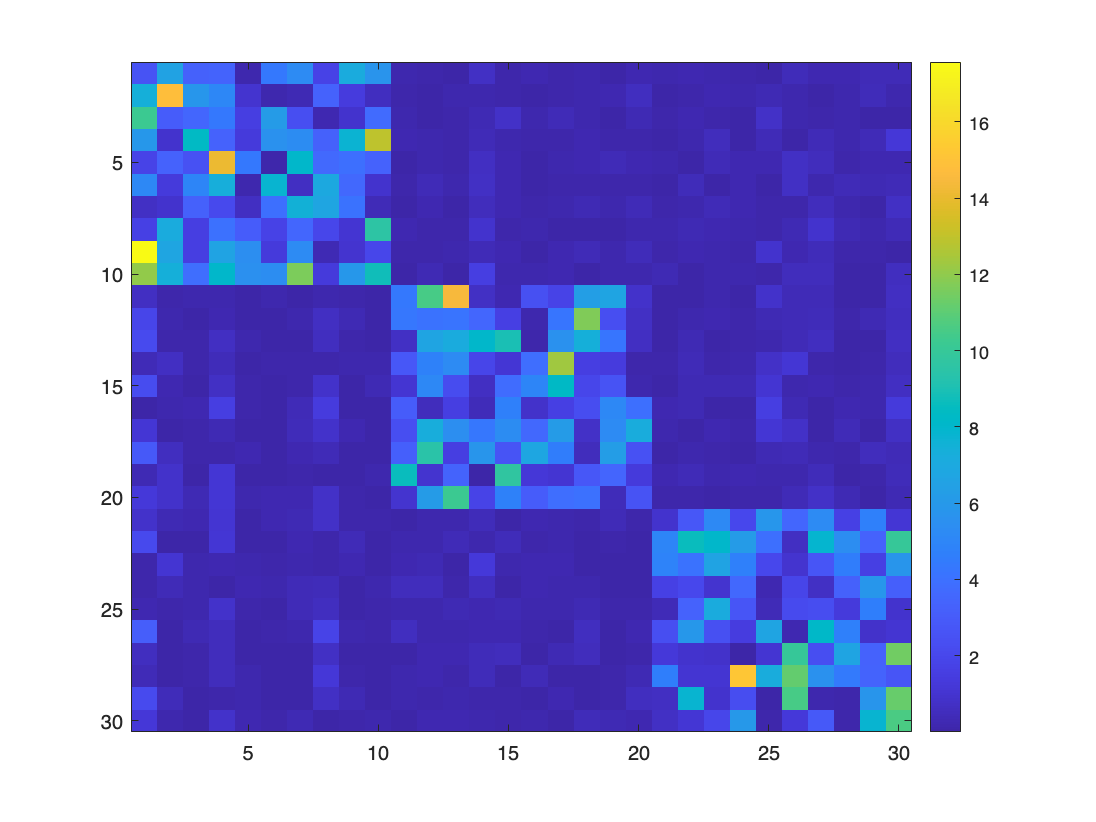

image(abs(w), 'CDataMapping', 'scaled')
colorbar

% MTFLC performance.
for i = 1: 5
    [ew, fv] = MTFLC_ADMM(X, Y, i, 1);
    sqrt(norm(ew - trueW, "fro")^2/900)
end

ADMM Config: [MaxIter 800][Tol 0.0001]
ADMM Subsolver Config: [MaxIter 5000][Tol 1e-08]
Iteration:  800


ans = 1.0598

ADMM Config: [MaxIter 800][Tol 0.0001]
ADMM Subsolver Config: [MaxIter 5000][Tol 1e-08]
Iteration:  800


ans = 1.1059

ADMM Config: [MaxIter 800][Tol 0.0001]
ADMM Subsolver Config: [MaxIter 5000][Tol 1e-08]
Iteration:  800


ans = 1.1526

ADMM Config: [MaxIter 800][Tol 0.0001]
ADMM Subsolver Config: [MaxIter 5000][Tol 1e-08]
Iteration:  800


ans = 1.1999

ADMM Config: [MaxIter 800][Tol 0.0001]
ADMM Subsolver Config: [MaxIter 5000][Tol 1e-08]
Iteration:  800


ans = 1.2476

for i = 1: 5
    [ew, fv] = MTFLC_ADMM(X, Y, 1, i);
    sqrt(norm(ew - trueW, "fro")^2/900)
end

ADMM Config: [MaxIter 800][Tol 0.0001]
ADMM Subsolver Config: [MaxIter 5000][Tol 1e-08]
Iteration:  800


ans = 1.0598

ADMM Config: [MaxIter 800][Tol 0.0001]
ADMM Subsolver Config: [MaxIter 5000][Tol 1e-08]
Iteration:  800


ans = 1.6124

ADMM Config: [MaxIter 800][Tol 0.0001]
ADMM Subsolver Config: [MaxIter 5000][Tol 1e-08]
Iteration:  800


ans = 1.9408

ADMM Config: [MaxIter 800][Tol 0.0001]
ADMM Subsolver Config: [MaxIter 5000][Tol 1e-08]
Iteration:  800


ans = 2.1535

ADMM Config: [MaxIter 800][Tol 0.0001]
ADMM Subsolver Config: [MaxIter 5000][Tol 1e-08]
Iteration:  800


ans = 2.3021

[ew, fv] = MTFLC_ADMM(X, Y, 1, 1);

ADMM Config: [MaxIter 800][Tol 0.0001]
ADMM Subsolver Config: [MaxIter 5000][Tol 1e-08]
Iteration:  800


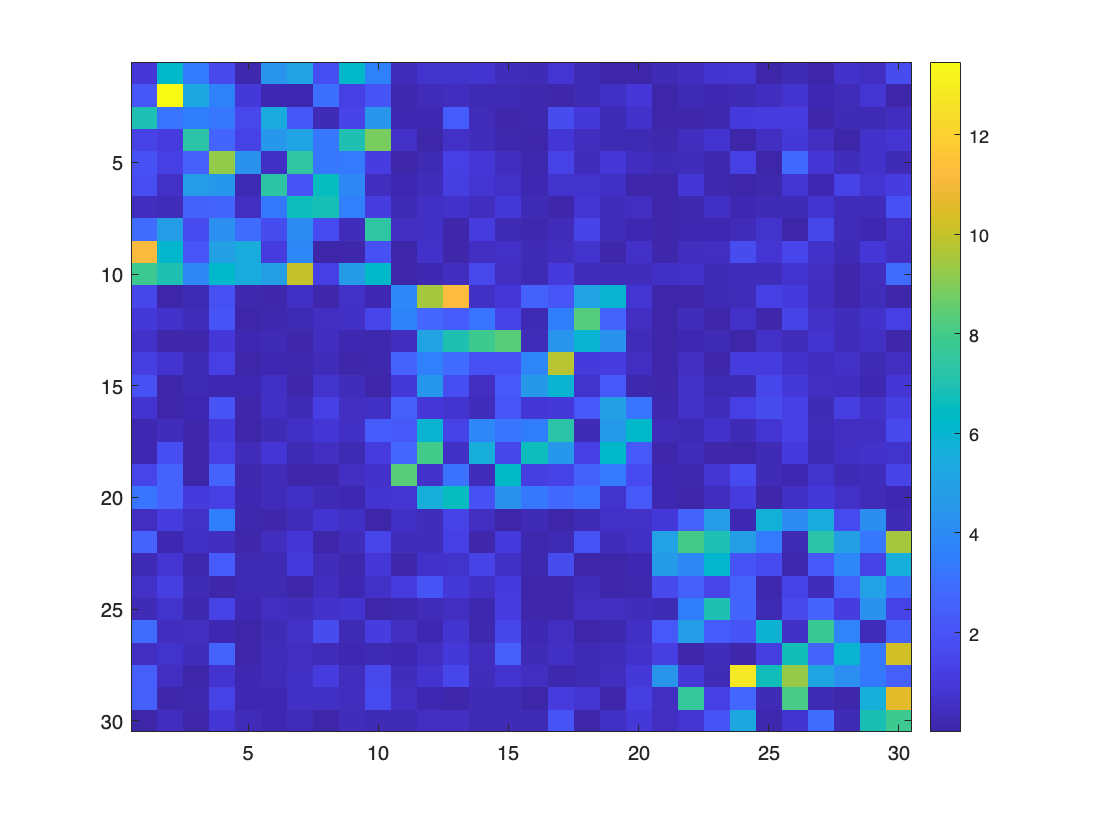

image(abs(ew), 'CDataMapping', 'scaled')
colorbar

sqrt(norm(w - trueW, "fro")/900)

ans = 3.6881

sqrt(norm(ew - trueW, "fro")/900)

ans = 6.1260

% Actual data.
data = load("multi-label datasets/genbase.mat");
dataX = data.data;
dataY = data.target.';
trainX = {};
trainY = {};
for i = 1: 27
    trainX{i} = dataX(1: 500, :);
    trainY{i} = dataY(1: 500, i);
end
testX = dataX(501: 662, :);
testY = dataY(501: 662, :);

d = importdata("regression/parkinosns/parkinsons_updrs.data")

d = struct with fields:
          data: [5875×22 double]
      textdata: {1×22 cell}
    colheaders: {1×22 cell}


d.textdata

ans = 1×22 cell array
    {'subject#'}    {'age'}    {'sex'}    {'test_time'}    {'motor_UPDRS'}    {'total_UPDRS'}    {'Jitter(%)'}    {'Jitter(Abs)'}    {'Jitter:RAP'}    {'Jitter:PPQ5'}    {'Jitter:DDP'}    {'Shimmer'}    {'Shimmer(dB)'}    {'Shimmer:APQ3'}    {'Shimmer:APQ5'}    {'Shimmer:APQ11'}    {'Shimmer:DDA'}    {'NHR'}    {'HNR'}    {'RPDE'}    {'DFA'}    {'PPE'}


d.colheaders

ans = 1×22 cell array
    {'subject#'}    {'age'}    {'sex'}    {'test_time'}    {'motor_UPDRS'}    {'total_UPDRS'}    {'Jitter(%)'}    {'Jitter(Abs)'}    {'Jitter:RAP'}    {'Jitter:PPQ5'}    {'Jitter:DDP'}    {'Shimmer'}    {'Shimmer(dB)'}    {'Shimmer:APQ3'}    {'Shimmer:APQ5'}    {'Shimmer:APQ11'}    {'Shimmer:DDA'}    {'NHR'}    {'HNR'}    {'RPDE'}    {'DFA'}    {'PPE'}


d.data

ans =     1.0000   72.0000         0    5.6431   28.1990   34.3980    0.0066    0.0000    0.0040    0.0032    0.0120    0.0256    0.2300    0.0144    0.0131    0.0166    0.0431    0.0143   21.6400    0.4189    0.5484    0.1601
    1.0000   72.0000         0   12.6660   28.4470   34.8940    0.0030    0.0000    0.0013    0.0015    0.0040    0.0202    0.1790    0.0099    0.0107    0.0169    0.0298    0.0111   27.1830    0.4349    0.5648    0.1081
    1.0000   72.0000         0   19.6810   28.6950   35.3890    0.0048    0.0000    0.0021    0.0021    0.0062    0.0168    0.1810    0.0073    0.0084    0.0146    0.0220    0.0202   23.0470    0.4622    0.5441    0.2101
    1.0000   72.0000         0   25.6470   28.9050   35.8100    0.0053    0.0000    0.0019    0.0026    0.0057    0.0231    0.3270    0.0111    0.0126    0.0196    0.0332    0.0278   24.4450    0.4873    0.5779    0.3328
    1.0000   72.0000         0   33.6420   29.1870   36.3750    0.0034    0.0000    0.0009    0.0013    0.0028

iter = 1;
pX = {};
pY = {};
for i = 1: 42
    for j = iter: 5875
        if d.data(j, 1) ~= i
            pX{i} = d.data(iter: j-1, 7: 22);
            pY{i} = d.data(iter: j-1, 6);
            iter = j;
            break;
        end
        if i == 42
            pX{i} = d.data(iter: 5875, 7: 22);
            pY{i} = d.data(iter: 5875, 6);
            break;
        end
    end
end

initilization done
r&c done
Iteration:   60

ans = 8.1612

initilization done
r&c done
Iteration:   52

ans = 8.2151

initilization done
r&c done
Iteration:   48

ans = 8.2671

initilization done
r&c done
Iteration:   45

ans = 8.3169

initilization done
r&c done
Iteration:   44

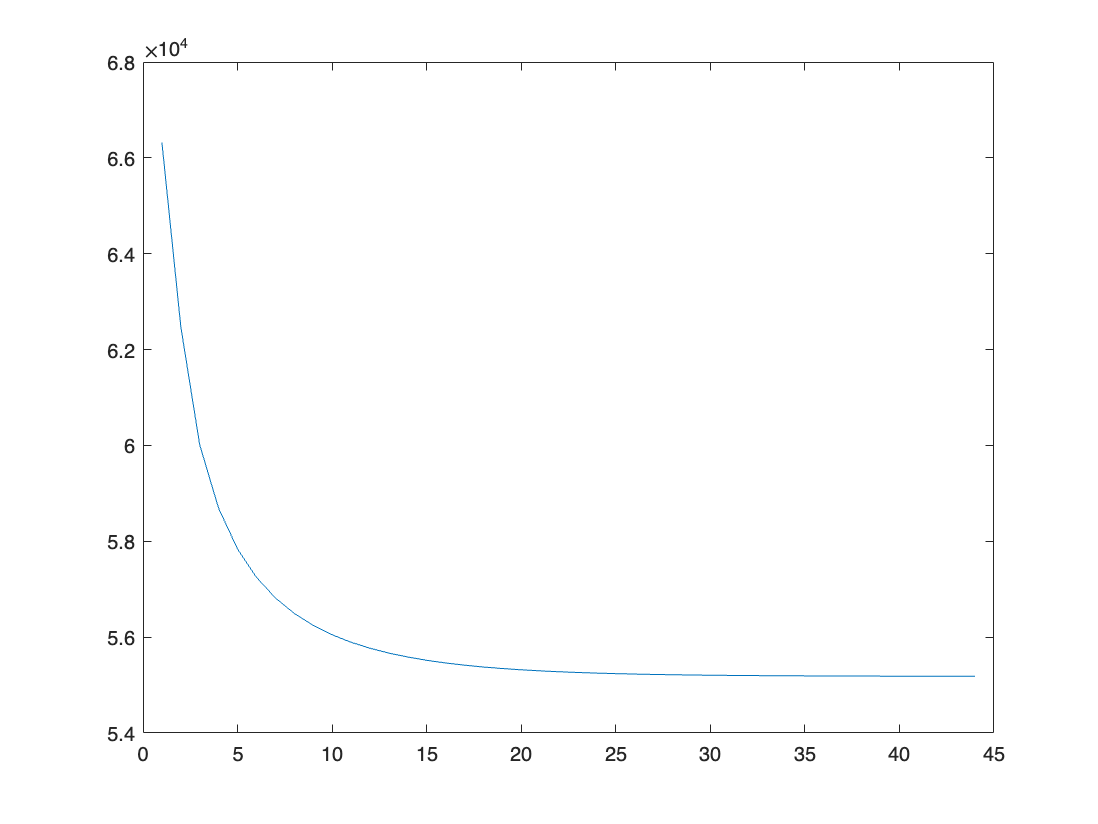

ans = 8.3642

for i = 1: 5
    rmserw = 0;
    rew = multitask_admm(pY, pX, 1, 1, 1e-5, i, 1);
    for j = 1: 42
        rmserw = rmserw + sqrt(norm(pX{j}*rew(:, j) - pY{j}, 2)^2/16);
    end
    rmserw / 42
end

initilization done
r&c done
Iteration:   60

ans = 8.1612

initilization done
r&c done
Iteration:   72

ans = 8.1946

initilization done
r&c done
Iteration:   46

ans = 8.2343

initilization done
r&c done
Iteration:   80

ans = 8.2670

initilization done
r&c done
Iteration:   51

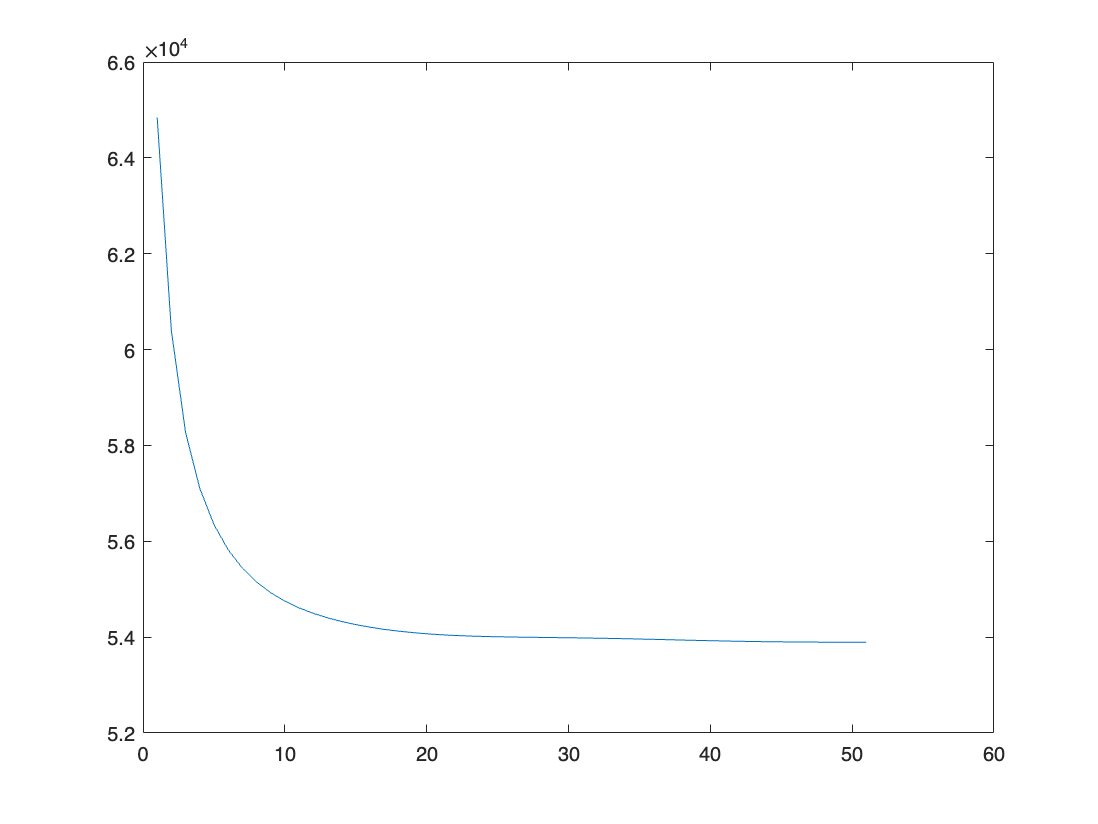

ans = 8.3013

for i = 1: 5
    rmserw = 0;
    rew = multitask_admm(pY, pX, 1, 1, 1e-5, 1, i);
    for j = 1: 42
        rmserw = rmserw + sqrt(norm(pX{j}*rew(:, j) - pY{j}, 2)^2/16);
    end
    rmserw / 42
end

for i = 1: 5
    rmseew = 0;
    eew = MTFLC_ADMM(pX, pY, i, 1);
    for j = 1: 42
        rmseew = rmseew + sqrt(norm(pX{j}*eew(:, j) - pY{j}, 2)^2/16);
    end
    rmseew / 42
end

ADMM Config: [MaxIter 800][Tol 0.0001]
ADMM Subsolver Config: [MaxIter 5000][Tol 1e-08]
Iteration:  234


ans = 11.7479

ADMM Config: [MaxIter 800][Tol 0.0001]
ADMM Subsolver Config: [MaxIter 5000][Tol 1e-08]
Iteration:  275


ans = 11.9207

ADMM Config: [MaxIter 800][Tol 0.0001]
ADMM Subsolver Config: [MaxIter 5000][Tol 1e-08]
Iteration:  307


ans = 12.0914

ADMM Config: [MaxIter 800][Tol 0.0001]
ADMM Subsolver Config: [MaxIter 5000][Tol 1e-08]
Iteration:  317


ans = 12.2625

ADMM Config: [MaxIter 800][Tol 0.0001]
ADMM Subsolver Config: [MaxIter 5000][Tol 1e-08]
Iteration:  325


ans = 12.4261

for i = 1: 5
    rmseew = 0;
    eew = MTFLC_ADMM(pX, pY, 1, i);
    for j = 1: 42
        rmseew = rmseew + sqrt(norm(pX{j}*eew(:, j) - pY{j}, 2)^2/16);
    end
    rmseew / 42
end

ADMM Config: [MaxIter 800][Tol 0.0001]
ADMM Subsolver Config: [MaxIter 5000][Tol 1e-08]
Iteration:  234


ans = 11.7479

ADMM Config: [MaxIter 800][Tol 0.0001]
ADMM Subsolver Config: [MaxIter 5000][Tol 1e-08]
Iteration:  270


ans = 12.4128

ADMM Config: [MaxIter 800][Tol 0.0001]
ADMM Subsolver Config: [MaxIter 5000][Tol 1e-08]
Iteration:  260


ans = 12.6712

ADMM Config: [MaxIter 800][Tol 0.0001]
ADMM Subsolver Config: [MaxIter 5000][Tol 1e-08]
Iteration:  290


ans = 12.8064

ADMM Config: [MaxIter 800][Tol 0.0001]
ADMM Subsolver Config: [MaxIter 5000][Tol 1e-08]
Iteration:  320


ans = 12.8914

initilization done
r&c done
Iteration:   60

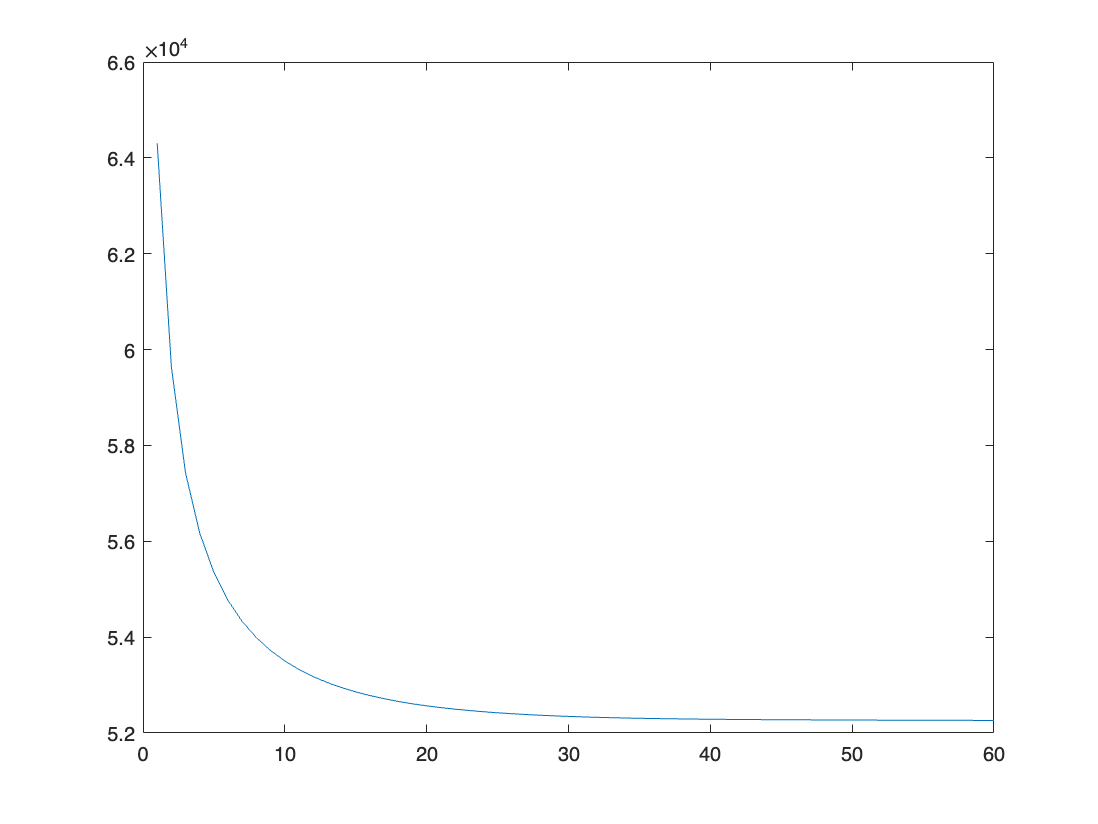

rew = multitask_admm(pY, pX, 1, 1, 1e-5, 1, 1);

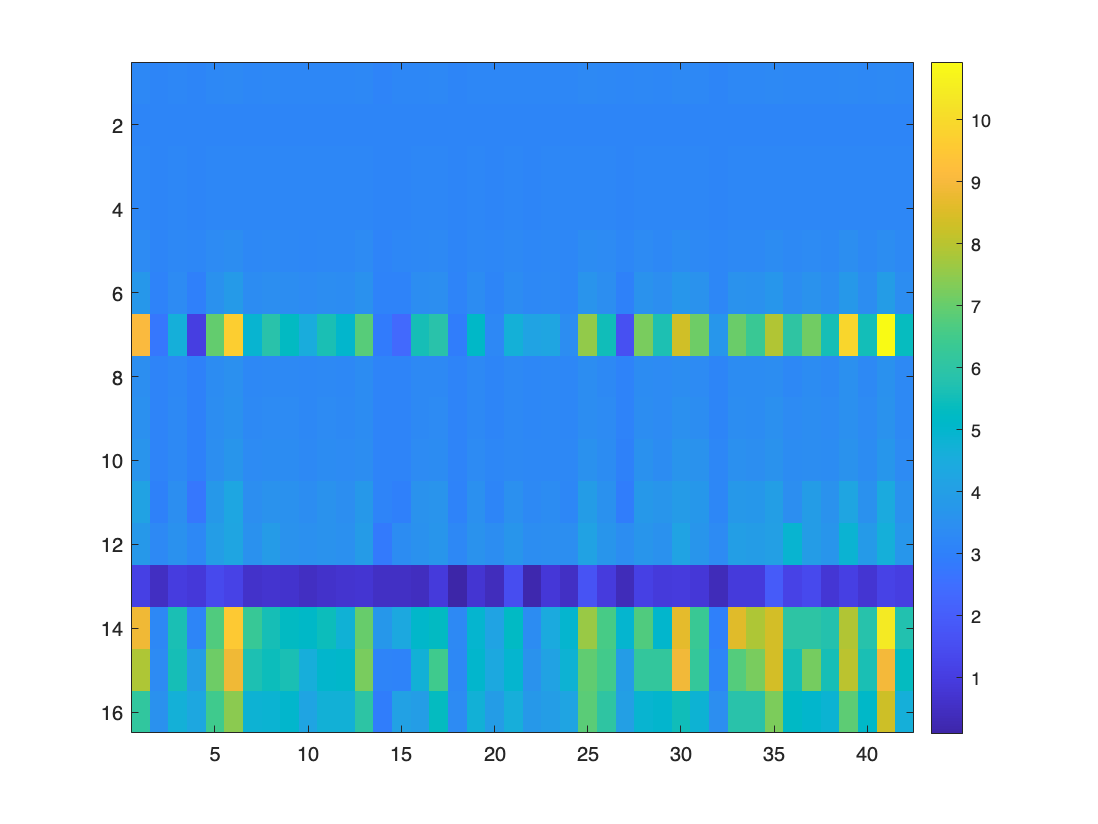

image(abs(rew), 'CDataMapping', 'scaled')
colorbar

eew = MTFLC_ADMM(pX, pY, 1, 1);

ADMM Config: [MaxIter 800][Tol 0.0001]
ADMM Subsolver Config: [MaxIter 5000][Tol 1e-08]
Iteration:  234


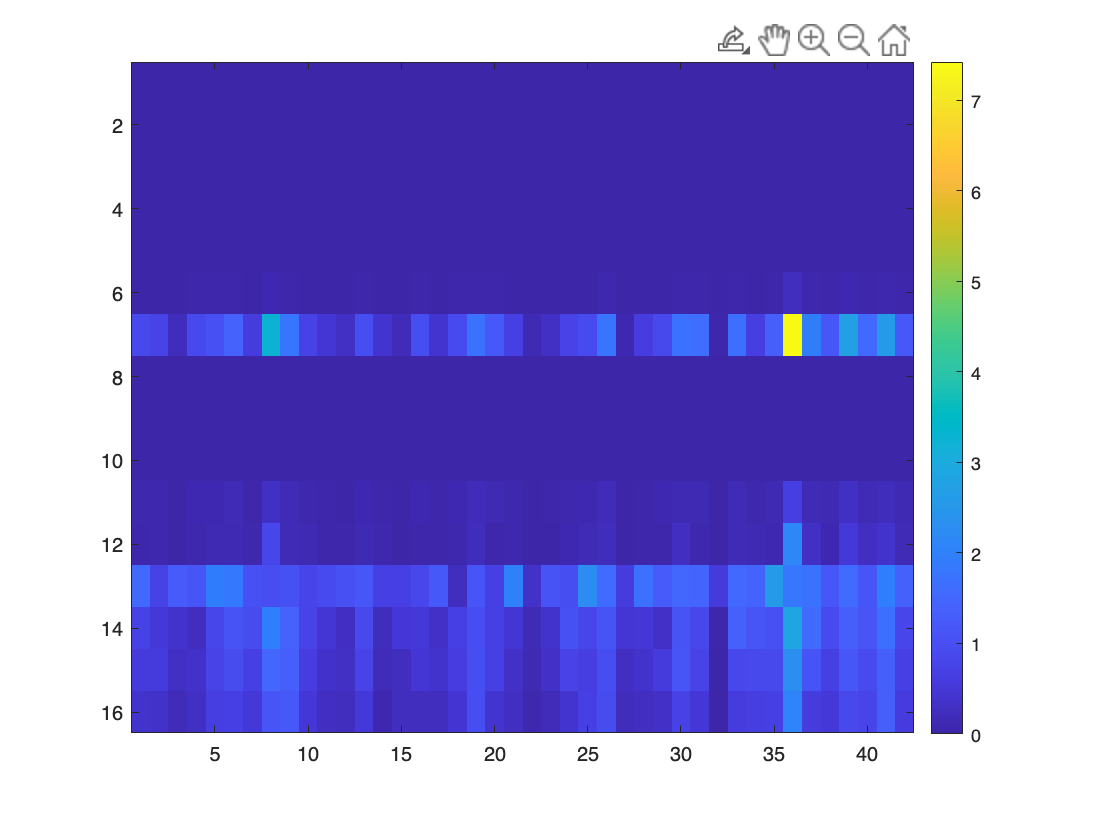

image(abs(eew), 'CDataMapping', 'scaled')
colorbar

rmserw = 0;
rmseew = 0;
for i = 1: 42
    rmserw = rmserw + sqrt(norm(pX{i}*rew(:, i) - pY{i}, 2)/16);
    rmseew = rmseew + sqrt(norm(pX{i}*eew(:, i) - pY{i}, 2)/16);
end
rmserw / 42

ans = 1.5320

rmseew / 42

ans = 1.6782

rew

rew =     0.5215    0.4462    0.4543    0.4604    0.5217    0.5874    0.4723    0.6735    0.5544    0.4547    0.4480    0.4428    0.5177    0.4401    0.4317    0.4555    0.4768    0.4172    0.5319    0.4423    0.4853    0.4132    0.4370    0.4572    0.5408    0.5825    0.4240    0.4997    0.4674    0.7356    0.5318    0.4103    0.5456    0.5124    0.5744    0.8622    0.6132    0.4873    0.7526    0.5210    0.7638    0.5073
    0.4530    0.3999    0.4085    0.4095    0.4507    0.4878    0.4174    0.5136    0.4600    0.4040    0.4036    0.3996    0.4460    0.3949    0.3915    0.4104    0.4186    0.3805    0.4386    0.3986    0.4300    0.3785    0.3971    0.4123    0.4595    0.4754    0.3862    0.4336    0.4188    0.5154    0.4598    0.3779    0.4690    0.4427    0.4823    0.6379    0.5138    0.4279    0.5496    0.4463    0.5803    0.4397
    0.4897    0.4246    0.4334    0.4367    0.4883    0.5426    0.4460    0.6046    0.5114    0.4308    0.4269    0.4225    0.4842    0.4197    0.4126  

eew

eew =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  